dataset_path = fullfile('G:\MEngg Materials\Sem 3\ENGN 8535 Data Analytics\Dataset\hpl\hpl_final\hpl_final_jpg\');
imds = imageDatastore(dataset_path, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
network_path = fullfile('G:\MEngg Materials\Sem 3\ENGN 8535 Data Analytics\Project\Data-analytics\net3.mat');
net = load(network_path);
% images = imageSet(dataset_path);
% perm = randperm(49676,20);
% for i = 1:20
%     subplot(4,5,i);
%     imshow(imds.Files{perm(i)});
% end
% labelCount = countEachLabel(imds)
% img = readimage(imds,1);
% size(img)
% numTrainFiles = 274;
layer = 2;
name = net.net3.Layers(layer).Name;
channels = 1:8;
I = deepDreamImage(net.net3,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |       180.86 |               1 |
|           2 |       176.90 |               1 |
|           3 |       172.94 |               1 |
|           4 |       168.98 |               1 |
|           5 |       165.02 |               1 |
|           6 |       161.06 |               1 |
|           7 |       157.10 |               1 |
|           8 |       153.14 |               1 |
|           9 |       149.17 |               1 |
|          10 |       145.21 |               1 |
|==============================================|


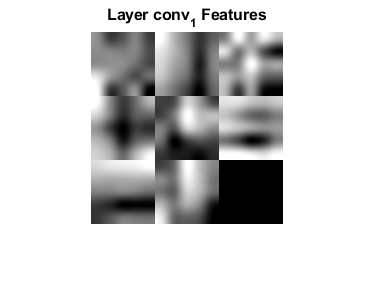

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

layer = 7;
name = net.net3.Layers(layer).Name;
channels = 1:16;
I = deepDreamImage(net.net3,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         1.64 |               1 |
|           2 |         2.07 |               1 |
|           3 |         2.52 |               1 |
|           4 |         2.86 |               1 |
|           5 |         3.15 |               1 |
|           6 |         3.38 |               1 |
|           7 |         3.59 |               1 |
|           8 |         3.78 |               1 |
|           9 |         3.97 |               1 |
|          10 |         4.12 |               1 |
|==============================================|


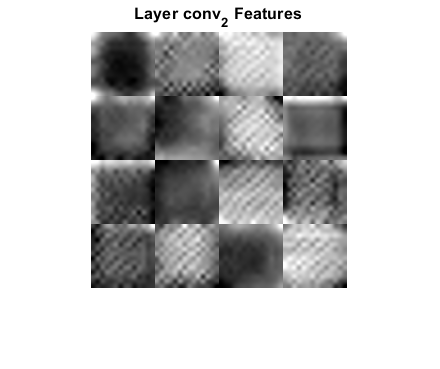

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

layer = 12;
name = net.net3.Layers(layer).Name;
channels = 1:32;
I = deepDreamImage(net.net3,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         0.39 |               1 |
|           2 |         0.09 |               1 |
|           3 |         0.41 |               1 |
|           4 |         0.83 |               1 |
|           5 |         1.17 |               1 |
|           6 |         1.47 |               1 |
|           7 |         1.74 |               1 |
|           8 |         1.97 |               1 |
|           9 |         2.18 |               1 |
|          10 |         2.36 |               1 |
|==============================================|


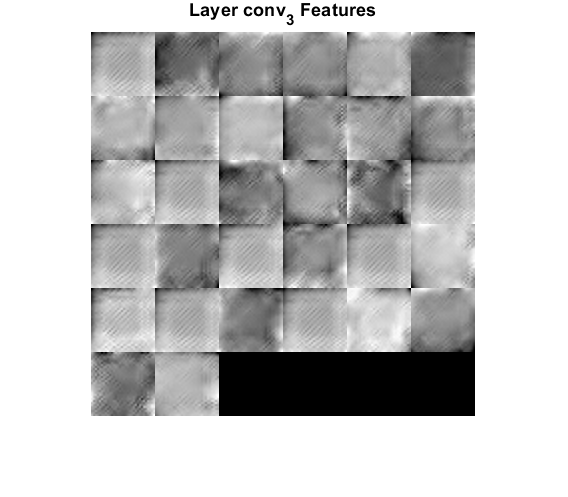

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

layer = 17;
name = net.net3.Layers(layer).Name;
channels = 1:64;
I = deepDreamImage(net.net3,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         0.15 |               1 |
|           2 |         0.15 |               1 |
|           3 |         0.55 |               1 |
|           4 |         0.84 |               1 |
|           5 |         1.07 |               1 |
|           6 |         1.26 |               1 |
|           7 |         1.43 |               1 |
|           8 |         1.60 |               1 |
|           9 |         1.73 |               1 |
|          10 |         1.83 |               1 |
|==============================================|


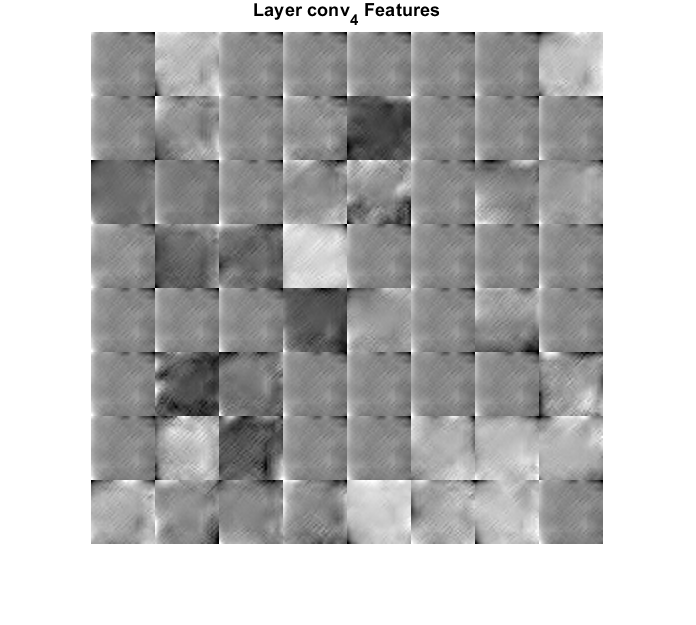

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

layer = 22;
name = net.net3.Layers(layer).Name;
channels = 1:128;
I = deepDreamImage(net.net3,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         0.02 |               1 |
|           2 |         0.34 |               1 |
|           3 |         0.79 |               1 |
|           4 |         0.98 |               1 |
|           5 |         1.21 |               1 |
|           6 |         1.38 |               1 |
|           7 |         1.57 |               1 |
|           8 |         1.56 |               1 |
|           9 |         1.77 |               1 |
|          10 |         1.81 |               1 |
|==============================================|


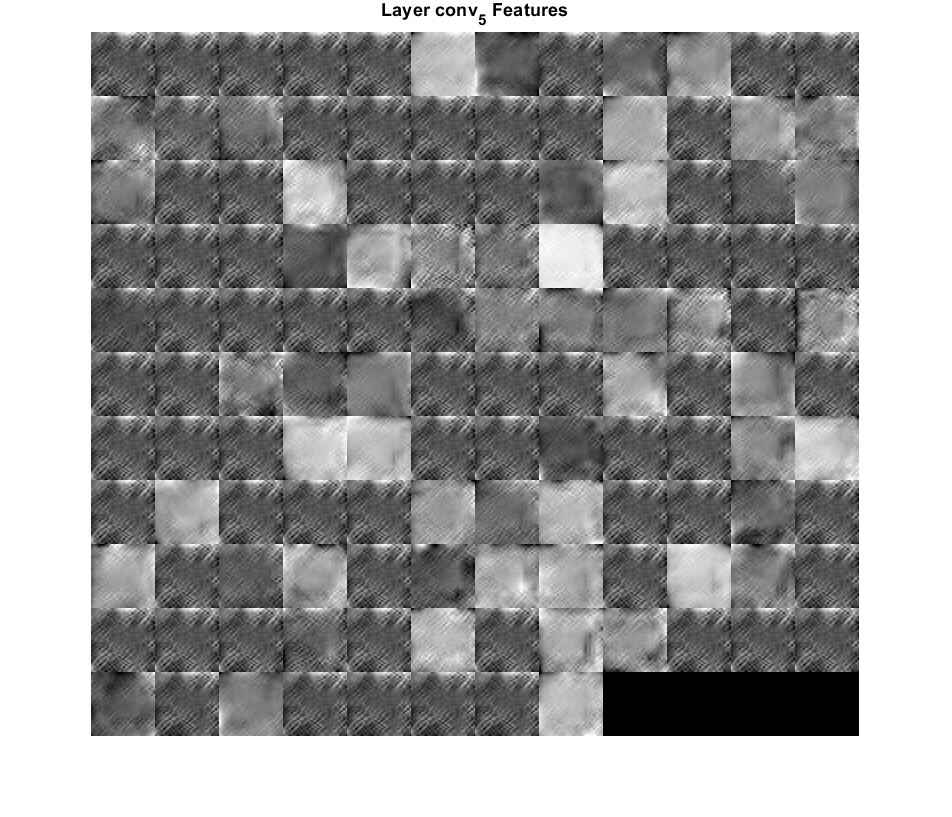

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

[imdsTrain,imdsTest,imdsVal] = splitEachLabel(imds,0.7, 0.15, 0.15,'randomized');
test_results = char(classify(net.net3,imdsTest));
count = 0;
TestLabels = char(imdsTest.Labels);
for i = 1:length(test_results)
    comp = strcmp(TestLabels(i,:), test_results(i,:));
    if (comp == 1)
        count = count + 1;
    end
end
test_accuracy = count/length(test_results)

test_accuracy = 0.5444